% sanity_check.m


# Sanity check

clear;
clc;

# Build rhythmic mRNA degradation model and construct parameter distribution

Rhythmic_mRNA_model = bbModel(@Sarah_Rhythmic_mRNA,5,3,'OutputType',[0 0 0]);

p = 4; % group number
q = 10; % group size
d = 5; % number of parameters 
index = 2; % the ith parameter 

% create parameter distribution
size = 10000;

amp_pd = makedist('Uniform','lower',0,'upper',1);
phase_pd = makedist('Uniform','lower',0,'upper',24);

Kd_pd_log= makedist('Uniform','lower',-1.58,'upper',1.415);
Kd_pd = 10.^random(Kd_pd_log,[size,1]);

params = {amp_pd phase_pd Kd_pd amp_pd phase_pd};


# Histogram of parameter Kd

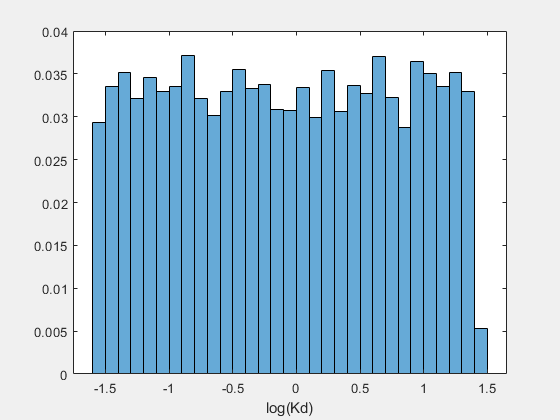

f = figure;
set(f, 'Visible', 'on');
histogram(log10(Kd_pd),'Normalization','probability')
xlabel('log(Kd)')

# Parameter sampling

### Unit cube

Single unit cube correspopnds to the parameter samples for single Sobol indices calculation, where the ith parameter values are fixed within each group and other parameter values unfixed. All parameter values are varied across groups (indicated by different colors). 

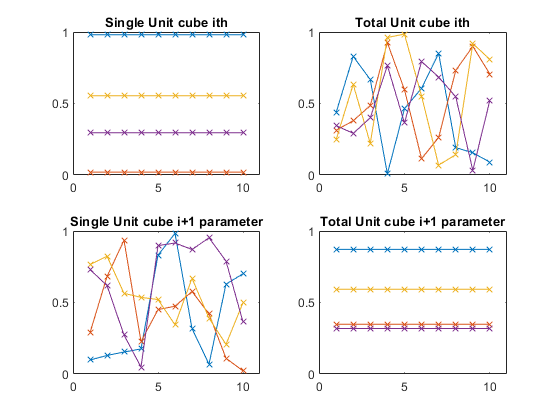

[SingleCube,TotalCube] = generate_Nested_cube(p,q,d,index);

figure;
for j=1:p
   subplot(2,2,1)
   plot(1:q,SingleCube(j,:,index)','-x');
   hold on; 
   xlim([0 q+1]);
   ylim([0 1])
   title('Single Unit cube ith')
end 
hold off;


for j=1:p
   subplot(2,2,2)
   plot(1:q,TotalCube(j,:,index)','-x');
   hold on; 
   xlim([0 q+1]);
   ylim([0 1])
   title('Total Unit cube ith')
end   
hold off;

for j=1:p
   subplot(2,2,3)
   plot(1:q,SingleCube(j,:,index+1)','-x');
   hold on; 
   xlim([0 q+1]);
   ylim([0 1])
   title('Single Unit cube i+1 parameter')
end    
hold off;

for j=1:p
   subplot(2,2,4)
   plot(1:q,TotalCube(j,:,index+1)','-x');
   hold on; 
   xlim([0 q+1]);
   ylim([0 1])
   title('Total Unit cube i+1 parameter')
end   
hold off

# Parameter space

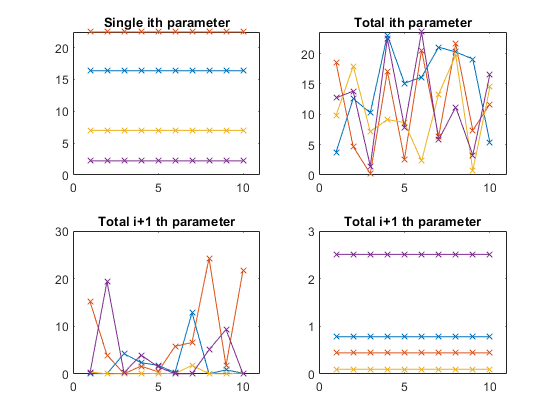

[SinglePar,TotalPar] = generate_Nested_Parameter(params,p,q,d,index);

figure;
for j=1:p
   subplot(2,2,1)
   plot(1:q,SinglePar(j,:,index)','-x');
   hold on; 
   xlim([0 q+1]);  
   title('Single ith parameter')
  
end      
hold off;   

for j=1:p   
   subplot(2,2,2)
   plot(1:q,TotalPar(j,:,index)','-x');
   hold on; 
   xlim([0 q+1]);
   title('Total ith parameter')  
end   
hold off;


for j=1:p   
   subplot(2,2,3)
   plot(1:q,SinglePar(j,:,index+1)','-x');
   hold on; 
   xlim([0 q+1]);
   title('Total i+1 th parameter')  
end   
hold off;
for j=1:p   
   subplot(2,2,4)
   plot(1:q,TotalPar(j,:,index+1)','-x');
   hold on; 
   xlim([0 q+1]);
   title('Total i+1 th parameter')  
end   
hold off;

# Parameter from AB Sampling

N = 10;
d = 5;
[par_A,par_B,par_AB] = generate_AB_Parameter(N,d,params);

par_A =     0.7072    8.1045    0.9241    0.4609   15.6083
    0.3335   12.6189    0.1568    0.5656   21.5597
    0.2363    5.0604    0.0327    0.6837   14.2152
    0.6623   15.3811    0.0834    0.9881    6.9633
    0.0141   18.8014    2.9898    0.8257    2.0325
    0.9081    3.4286    0.2847    0.1865    9.9411
    0.4586   11.3678    0.0816    0.3697    3.0196
    0.1305   23.0563    5.3642    0.2572    8.4307
    0.8040   19.7671    0.0722    0.7060   17.3286
    0.5848    2.0924    8.7245    0.0422   23.3559


par_B =     0.7761   20.8122    0.0578    0.0874    3.3261
    0.8217    9.7299    0.0753    0.7458   20.4084
    0.1094   17.0080    0.2682    0.9743   13.1391
    0.6820    7.2268    2.1649    0.6080   17.5663
    0.2080   12.7514    0.1196    0.3733   21.9603
    0.9158    5.7562    0.0290    0.2388    6.2793
    0.5715    2.5845    4.8343    0.8444    7.3819
    0.4426    0.1402    3.1182    0.4208    0.7446
    0.3517   22.9025    3.5297    0.1370    9.7998
    0.0875   14.7495    0.5576    0.5745   15.3409


par_AB =     0.7761    8.1045    0.9241    0.4609   15.6083
    0.8217   12.6189    0.1568    0.5656   21.5597
    0.1094    5.0604    0.0327    0.6837   14.2152
    0.6820   15.3811    0.0834    0.9881    6.9633
    0.2080   18.8014    2.9898    0.8257    2.0325
    0.9158    3.4286    0.2847    0.1865    9.9411
    0.5715   11.3678    0.0816    0.3697    3.0196
    0.4426   23.0563    5.3642    0.2572    8.4307
    0.3517   19.7671    0.0722    0.7060   17.3286
    0.0875    2.0924    8.7245    0.0422   23.3559



% figure;
% subplot(1,3,1)
% for i=1:d
%     plot(ones(N,1)*i,par_A(:,i),'-x');
%     hold on;
% end
% hold off;

% subplot(1,3,2)
% for i=1:d
%     plot(ones(N,1)*i,par_B(:,i),'-^');
% end
% 
% subplot(1,3,3)
% for i=1:d
%     
%     
% end

# Comparision between AB Sampling and Nested Sampling with group size = 2

### **Non-circular AB Sampling**

% tStart = tic;
% % hyper parameter for batch run
% batch_size = 10;
% 
% 
% % batch run
% input_number = Rhythmic_mRNA_model.ParNumber;
% output_number = Rhythmic_mRNA_model.OutputNumber;
% 
% S1_batch = zeros(batch_size,output_number,input_number);
% ST_batch = zeros(batch_size,output_number,input_number);
% 
% f = waitbar(0,'Start batch running ...');
% 
% for i=1:batch_size
%     % update waitbar
%     waitbar(i/batch_size, f, sprintf('Progress: %d %%', floor(i/batch_size*100)));
%    
%     
%     [S1, ST] = CircularSobol(Rhythmic_mRNA_model, params,'method','nonCircular','SampleSize',10^3,'formula',1,...
%                                                             'GroupNumber',1000,'GroupSize',2,'plot',0,'progress',0);
%     S1_batch(i,:,:) = S1;
%     ST_batch(i,:,:) = ST;
%     
%     fprintf('Finished running the batch %d \n',i);
% end
% 
% close(f); % close wait bar
% 
% % calculate mean and std 
% mean_S1 = mean(S1_batch);
% std_S1 = std(S1_batch);
% 
% mean_ST = mean(ST_batch);
% std_ST = std(ST_batch);
% 
% %plot_matrix = [S1_plot;ST_plot]';
% mean_matrix = [mean_S1;mean_ST];
% error_matrix = [std_S1;std_ST];
% 
% for i=1:output_number
%     
%     figure;
%     tmp_mean = reshape(mean_matrix(:,i,:),[2,input_number])';
%     b = bar(tmp_mean,'grouped');
% 
%     % plot error bar
%     tmp_error = reshape(error_matrix(:,i,:),[2,input_number])';
% 
%     hold on;
%     % Find the number of groups and the number of bars in each group
%     [ngroups,nbars] = size(tmp_mean);
%     
%     % for R2019a and earlier
% 
%     % Calculate the width for each bar group
%     groupwidth = min(0.8, nbars/(nbars + 1.5));
%     
%     % Set the position of each error bar in the centre of the main bar
%     for j = 1:nbars
%         % Calculate center of each bar
%         x = (1:ngroups) - groupwidth/2 + (2*j-1) * groupwidth / (2*nbars);
%         errorbar(x, tmp_mean(:,j), tmp_error(:,j), 'k', 'linestyle', 'none');
%     end
%     
% %     % for R2019b and later
% %     % Calculate the width for each bar group
% %     x_cor = nan(nbars, ngroups);
% %     for j = 1:nbars
% %         x_cor(j,:) = b(j).XEndPoints;
% %     end 
% %     % Plot the errorbars
% %     errorbar(x_cor',tmp_mean,tmp_error,'k','linestyle','none');
%     
%     hold off
% 
%     ylim([0 1])
%     legend('Single','Total')
%     legend boxoff
%     yticks(0:.5:1)
%     set(gca,'FontSize',20)
%     set(gca,'LineWidth',2)
% end
% 
% tEnd = toc(tStart);
% fprintf('The running took %s \n', duration([0, 0, tEnd]));

# Check Nested Sampling scheme 

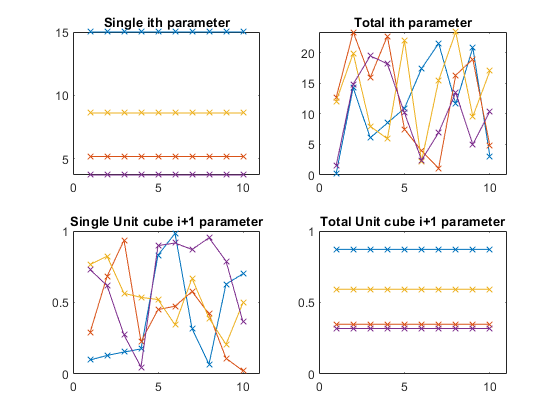

[SinglePar,TotalPar] = generate_Nested_Parameter(params,p,q,d,index);
figure;

for j=1:p
   subplot(2,2,1)
   plot(1:q,SinglePar(j,:,index)','-x');
   hold on; 
   xlim([0 q+1]);  
   title('Single ith parameter')
  
end      
hold off;   

for j=1:p   
   subplot(2,2,2)
   plot(1:q,TotalPar(j,:,index)','-x');
   hold on; 
   xlim([0 q+1]);
   title('Total ith parameter')  
end   
hold off;
for j=1:p
   subplot(2,2,3)
   plot(1:q,SingleCube(j,:,index+1)','-x');
   hold on; 
   xlim([0 q+1]);
   ylim([0 1])
   title('Single Unit cube i+1 parameter')
end    
hold off;

for j=1:p
   subplot(2,2,4)
   plot(1:q,TotalCube(j,:,index+1)','-x');
   hold on; 
   xlim([0 q+1]);
   ylim([0 1])
   title('Total Unit cube i+1 parameter')
end   
hold off

### Test Sobol indices calculation using Nested Sampling Scheme 

InputNumber = 5;
OutputNumber = 3;
OutputType = [0 0 0];
Formula = 1;
SampleSize = 10^4;
GroupNumber = 10;
GroupSize = 2;


total_Var = Var_Calculator(@Sarah_Rhythmic_mRNA,SampleSize,InputNumber,OutputNumber,params,OutputType,Formula);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


p = 10;
q = 2;
d = 5;
m = 3;
index = 2;


[SinglePar,TotalPar] = generate_Nested_Parameter(params,p,q,d,index);
 

%% run the model
Output_Single = zeros(p,q,m);
Output_Total = zeros(p,q,m);


for group_index = 1:p
    for row_index = 1:q
        tmp_par_single = reshape(SinglePar(group_index,row_index,:),[d,1]);
        tmp_par_total = reshape(TotalPar(group_index,row_index,:),[d,1]);
        
        Output_Single(group_index,row_index,:) = Sarah_Rhythmic_mRNA(tmp_par_single);
        Output_Total(group_index,row_index,:) = Sarah_Rhythmic_mRNA(tmp_par_total);            
    end
end

% check model input and output
model_input_single = SinglePar(7,1,:);
model_input_total = TotalPar(6,2,:);

Output_single_LFH = Sarah_Rhythmic_mRNA(model_input_single);
Output_total_LFH = Sarah_Rhythmic_mRNA(model_input_total);

Output_single_RFH = Output_Single(7,1,:);
Output_total_RFH = Output_Total(6,2,:);